clearvars
%=====USER INPUT - INIT VALUES/GIVENS/BOUNDARY COND
T = zeros(100,100);
for i = 1:100
    for j = 1:100
        T(i,j) = 50;
    end
end
T(:,1)   =  60; %left bc
T(:,end) =  50; %right bc
T(end,:) =   0; %top bc
T(1,:)   = 120; %bottom bc

lambda = 1.2    ; %relaxation (for 29.12)
e_s    = 0.00001; %iterate until this allowed error
%=====END USER INPUT

mx    = size(T);   %find how many rows and columns are to be calculated
maxX  = mx(1,2)-2; %number of columns in final T matrix
maxY  = mx(1,1)-2; %number of rows in final T matrix
e_a   = 1;         %initialize e_a to enter "while"
iters = 0;         %see how many iterations it takes

tic

while e_a > e_s %iterate until allowed error is reached
    e_a = 0;
    if iters > 3000 %to prevent infinite loops
        error('exceeds allowable iterations; iter>3000. comment out line 21 to bypass')
    end
    iters = iters + 1; %increase iteration counter by one
    for j = 2:maxY+1 %perform all rows
        for i = 2:maxX+1 %perform all columns
            T_old  = T(j,i); %store old value for relaxation and error calcs
            T(j,i) = (T(j+1,i)+T(j-1,i)+T(j,i+1)+T(j,i-1))/4; %new value by (29.11)
            T(j,i) = lambda*(T(j,i))+(1-lambda)*T_old; %(29.12)
            e_a_tmp = abs((T(j,i)-T_old)/T(j,i)); %(29.13)
            if e_a_tmp > e_a
                e_a = e_a_tmp;
            end
        end
    end
end

toc

Elapsed time is 102.155456 seconds.



%print results to console
fprintf('%g iterations were required.',iters);

2298 iterations were required.

fprintf('The maximum error is %.6f.',e_a);

The maximum error is 0.000010.

fprintf('The temperature values at each point are printed below:');

The temperature values at each point are printed below:

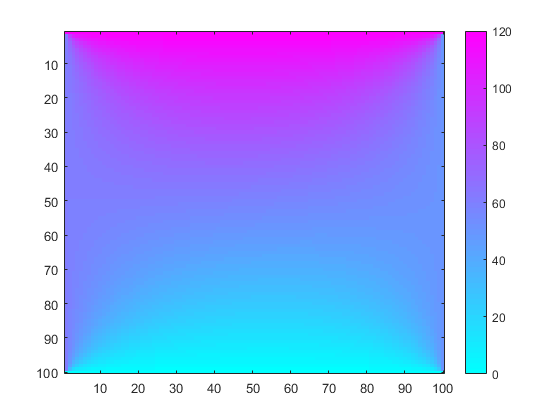


imagesc(T)
colormap cool;
hold on
colorbar
hold off